#### FIR Filter Test


% Equiripple Lowpass filter designed using the FIRPM function.

% All frequency values are in Hz.
Fs = 1500e3;               % Sampling Frequency

Fpass = 200e3;             % Passband Frequency
Fstop = 390e3;             % Stopband Frequency
Dpass = 0.057501127785;    % Passband Ripple
Dstop = 0.0001;            % Stopband Attenuation
dens  = 20;                % Density Factor
 
% Calculate the order from the parameters using FIRPMORD.
[N, Fo, Ao, W] = firpmord([Fpass, Fstop]/(Fs/2), [1 0], [Dpass, Dstop]);

% Calculate the coefficients using the FIRPM function.
b  = firpm(N, Fo, Ao, W, {dens});
Hd = dfilt.dffir(b);

% [EOF]

Fs must be kept at 1000Hz since that was what was used to generate the FIR coefficients

#### Creating Input signals

del_t = 1/Fs;
duration = 2e-4;
t = 0:del_t:duration;

freq = 100e3;        % 150 Khz signal
noise_freq = 450e3;  % 450 KHz high frequency noise

% Generating noisy signal
noise = 2*sin(2*pi*noise_freq*t);

% White noise generation
N_t = size(t);
N = N_t(1,2);
high = -0.2;
low = 0.1;
r = high + (low-high).*rand(N,1);
noise_coeff = 1.5;

% Generating original signal
original_signal = sin(2*pi*freq*t);

% Input signal with 450 kHz high frequency noise and random noise
input_signal = original_signal + noise + noise_coeff*transpose(r);


% freqz(coeff, 1, 512);
output_signal = filter(b, 1, input_signal);


#### Approximating FIR Filter coefficients to be 2^n if below a threshold

c = log2(abs(b));
c_floor = round(c);
c_diff = abs((c-c_floor)./c);


% Threshold value
% % Threshold = 0.045

% Threshold = 0.020; % appx =  8 at0.05% error
% Threshold = 0.025; % appx = 10 at ~6-7% error
% Threshold = 0.045; % appx = 14 at ~7-8% error
% Threshold = 0.050; % appx = 16 at ~7-9% error
% Threshold = 0.055; % appx = 18 at ~8-10% error
% Threshold = 0.065; % appx = 20 at ~12-15% error
Threshold = 0.075; % appx = 24 at ~25-30% error
% Threshold = 0.100; % appx = 26 at ~25-30% error
% Threshold = 0.200; % appx = 28 at ~80-100% error


mask_thresh = c_diff < Threshold;

% Create new coefficients array by masking and 2^c_new
c_new = c.*(1-mask_thresh)+c_floor.*mask_thresh;
mask_neg = b < 0;

coeff_abs = 2.^c_new;

% Creates a new coefficients matrix of things that have powers of 2 that
% are close enough
b_pow2 = coeff_abs .* (1-2 * mask_neg);

% Calculating new output signal using power of 2 approximated coefficients
output_signal_appx = filter(b_pow2, 1, input_signal);

#### Error calculation

% Calculating the RMSE of both signals compared to the original 
% Taking centre 80% of data

start_percent = 0.10;
end_percent = 1.00;

length_data = length(original_signal);
original_signal_sliced = original_signal(round(length_data*start_percent):round(length_data*end_percent));
output_signal_sliced = output_signal(round(length_data*start_percent):round(length_data*end_percent));
output_signal_appx_sliced = output_signal_appx(round(length_data*start_percent):round(length_data*end_percent));


rmse_FIR = sqrt(sum((original_signal_sliced - output_signal_sliced).^2) / length(original_signal_sliced));
rmse_appx = sqrt(sum((original_signal_sliced - output_signal_appx_sliced).^2) / length(original_signal_sliced));


error = rmse_appx/rmse_FIR*100-100;
disp(['ERROR: ', num2str(error), '%']);

ERROR: -0.010549%


num_approximated = sum(mask_thresh) % numder of coefficients that have been approximated to powers of 2

num_approximated = 14

#### Plotting

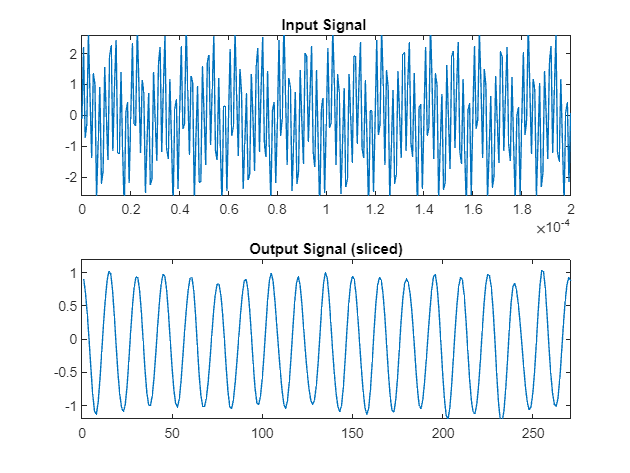

figure;
subplot(2,1,1);
plot(t,input_signal);
xlim([0, max(t)]);
ylim([-2.6, 2.6]);

title('Input Signal ');

subplot(2,1,2);
plot(output_signal_sliced);
xlim([0, length(original_signal_sliced)-1]);
ylim([-1.2, 1.2]);
title('Output Signal (sliced)');

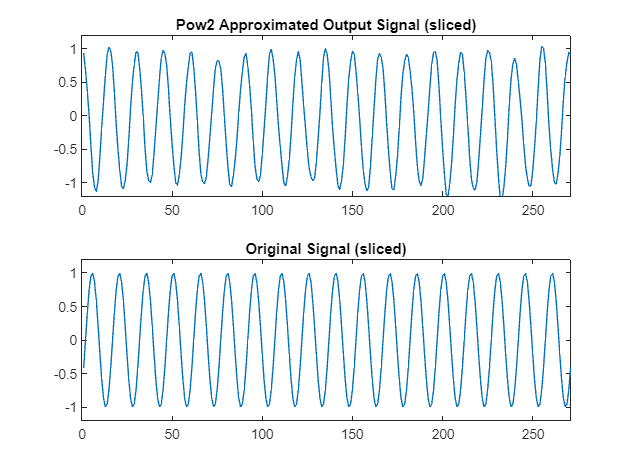


subplot(2,1,1);
plot(output_signal_appx_sliced);
xlim([0, length(original_signal_sliced)-1]);
ylim([-1.2, 1.2]);
title('Pow2 Approximated Output Signal (sliced)');

subplot(2,1,2);
plot(original_signal_sliced);
xlim([0, length(original_signal_sliced)-1]);
ylim([-1.2, 1.2]);
title('Original Signal (sliced)');

#### Save as .csv file

% Matrix to save
matrix = transpose(b_pow2);

% File name to save
filename = 'FIR_coefficients.csv';

% Save the matrix as a CSV file (comma-separated values)
writematrix(matrix, filename);


% Matrix to save
matrix_log2 = log2(abs(matrix));

% File name to save
filename = 'FIR_coefficientsBase2.csv';

% Save the matrix as a CSV file (comma-separated values)
writematrix(matrix_log2, filename);

% Save signal wave forms

